f_sampling = 250e6;
t_end = 0.1

t_end = 0.1000

t = 0 : 1/f_sampling : t_end

t =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000



f_0_original = 500e6;
axion_linewidth = f_0_original * 1e-6

axion_linewidth = 500

Q_axion = f_0_original / axion_linewidth;
f_0 = f_0_original / 10

f_0 = 50000000


de_broglie_wavelength = 2*pi * hbar_times_c / (axion_rest_energy * axion_velocity/c);
t_coherence = de_broglie_wavelength / axion_velocity;

f_axion = generate_axion_frequency(t, f_sampling, t_coherence, f_0, axion_linewidth);
signal = generate_axion_signal(t, f_sampling, f_axion, 1);
noise = randn(size(t));

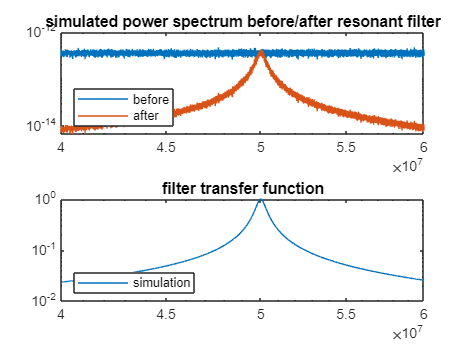

band_width = f_0 / 1e5 * 1e3;
bw = band_width / (f_sampling/2);
wo = f_0 / (f_sampling/2);  
[b, a] = iirpeak(wo, bw, 3);

filtered = filter(b, a, noise);

display_spectra(noise, filtered, f_sampling, [f_0 - 1e7, f_0 + 1e7]);

ratios = logspace(-4, -2, 10);
powers = zeros(size(ratios));
sigs = zeros(size(ratios));
noises = zeros(size(ratios));

wo = f_0 / (f_sampling/2);  

for i = 1 : length(ratios)
    disp(' ')
    Q = Q_axion * ratios(i)

    band_width = f_0 / Q;
    bw = band_width / (f_sampling/2);
    [b, a] = iirpeak(wo, bw);

    signal_out = filter(b, a, signal);
    noise_out = filter(b, a, noise);

    signal_power = bandpower(signal_out);
    noise_power = bandpower(noise_out);

    sigs(i) = signal_power;
    noises(i) = noise_power;

    power_gain = bandpower(signal_out) / bandpower(signal)
    powers(i) = power_gain;

    i_SNR = signal_power / noise_power;
    %powers(i) = i_SNR;
end

Q = 100

power_gain = 1.0000

Q = 166.8101

power_gain = 1.0000

Q = 278.2559

power_gain = 0.9999

Q = 464.1589

power_gain = 0.9999

Q = 774.2637

power_gain = 0.9997

Q = 1.2915e+03

power_gain = 0.9992

Q = 2.1544e+03

power_gain = 0.9979

Q = 3.5938e+03

power_gain = 0.9944

Q = 5.9948e+03

power_gain = 0.9852

Q = 10000

power_gain = 0.9622

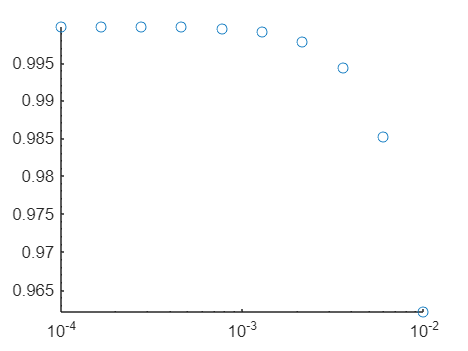

figure
scatter(ratios, powers)
set(gca, 'xscale','log', 'yscale','log')

ratios

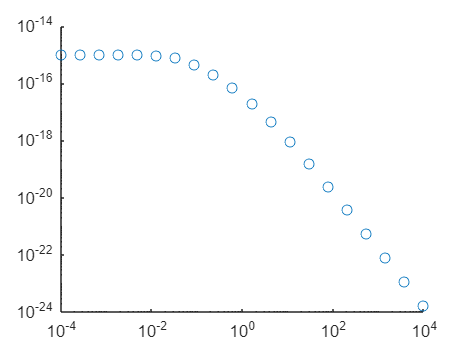

scatter(ratios, sigs)
set(gca, 'xscale','log', 'yscale','log')

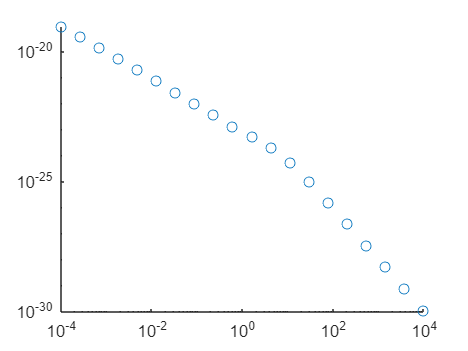

scatter(ratios, noises)
set(gca, 'xscale','log', 'yscale','log')